# Auxiliary anisotropic medium

## Introduction

**Illustrations of NIP and normal experiments in different auxiliary media**

**Authors**: I. Abakumov

**Publication date**: 1st of September 2019

**E-mail**: ivan.abakumov@fu-berlin.de

## Define working folder, add links to Library and SeisLab

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Create inhomogeneous model

G=GridClass;

%   [m]             [m]          [m]             [s]
G.x0 = -1000;     G.y0 = 0;    G.z0 = -500;        G.t0 = 0.00;         % initial point
G.nx =  2001;     G.ny = 1;    G.nz = 2551;     G.nt = 625;             % grid size
G.dx = 1;         G.dy = 0;    G.dz = 1;        G.dt = 0.008;           % grid step (meter)

G.gridInfo;

Information about grid:
x0=-1000, dx=1, Nx=2001.
y0=0, dy=0, Ny=1.
z0=-500, dz=1, Nz=2551.
t0=0, dt=0.008, Nt=625.


G.setGrid;
Gold = oldGrid(G);

## Make 2D velocity model

v0 = 1500; 
kappa = 0.5;
x0 = [0; 0]; 
xm = [-200 -65];
xp = [ 200 105]; 
Nxm = [-200 -71];
Nxp = [ 200 98]; 
gx0x = 1001;
gx0z = 501;
S  = [-500; 1000];
gSx  =  501;
gSz  = 1501;

velmod = zeros(G.nx,G.nz);

for i=1:G.nz
    velmod(:,i) = v0 + G.zz(i)*kappa; 
end
velmod_fig = velmod(:, 501:2001);

## Calculate traveltime NIP wave

%tti  = FSM2D(Gold,S,velmod); 

% Exact
tti = zeros(G.nx, G.nz);
for i=1:G.nx
    for j=1:G.nz
        Vs = v0 + kappa*S(2);                                              % velocity at the source point 
        Vr = v0 + kappa*G.zz(j);                                           % velocity at the point on reflector
        Rs = (S(1)-G.xx(i)).^2+(S(2)-G.zz(j)).^2;                          % distance from the source to the reflector point
        tti(i,j) = 1/kappa*acosh(1 + kappa^2*Rs./(2*Vs*Vr));               % traveltime in the medium with linear gradient of velocity 
    end
end

tti = tti(:,1:2001);

## Calculate stacking parameters (NIP)

% t0
t0 = 2*tti(gx0x, gx0z); 
    
% Vector w
w = zeros(2, 1); 
w(1) = (tti(gx0x+1,gx0z) - tti(gx0x-1,gx0z))/2;
w(2) = (tti(gx0x,gx0z+1) - tti(gx0x,gx0z-1))/2;
        
% Matrix M
M = tti(gx0x+1, gx0z) - 2*tti(gx0x, gx0z) + tti(gx0x-1, gx0z);

## Get wavefield attributes (NIP)

alpha = asin(w(1)*v0*sign(-w(1)));
    
RNIP = (cos(alpha))^2/M/v0;

## Definre reflector

alphar = atan(sin(alpha)/sqrt(v0^2/2000^2 - sin(alpha)^2));
R = 500; 
xr = S(1) + R*sin(alphar); 
zr = S(2) + R*cos(alphar); 
mtheta = -0.38*pi:pi/100:-0.28*pi;

## Calculate traveltime normal wave

%
ttiN = MLD('tti_normal_wave_exact.mat');

% % Exact
% ttiN = zeros(G.nx, G.nz);
% for i=1:G.nx
%     for j=1:G.nz
%         ts = @(r)(1/kappa*acosh(1 + kappa^2*((xr+R*cos(r)-G.xx(i)).^2+(zr+R*sin(r)-G.zz(j)).^2)/(2*(v0 + kappa*(zr+R*sin(r)))*(v0 + kappa*G.zz(j)))));
%         ttiN(i,j) = ts(fminbnd(ts, -pi, pi)); 
%     end
% end

## Calculate stacking parameters (Normal)

% Matrix N
N = ttiN(gx0x+1, gx0z) - 2*ttiN(gx0x, gx0z) + ttiN(gx0x-1, gx0z);

## Get wavefield attributes (Normal)

RN = (cos(alpha))^2/N/v0;

## Calculate trajectory of central ray

cray.xx = zeros(1,G.nx); 
cray.zz = zeros(1,G.nx);
cray.xx(1) = x0(1); 
cray.zz(1) = x0(2); 
xi = x2grid(cray.xx(1), G.x0, G.dx, G.nx);
zi = x2grid(cray.zz(1), G.z0, G.dz, G.nz);
T = tti(xi,zi);
dt = T/G.nx/1.002;
for i=1:G.nx
    xi = x2grid(cray.xx(i), G.x0, G.dx, G.nx);
    zi = x2grid(cray.zz(i), G.z0, G.dz, G.nz);
    px = (tti(xi+1,zi) - tti(xi,zi))/G.dx;
    pz = (tti(xi,zi+1) - tti(xi,zi))/G.dz;
    v2=1/(px^2 + pz^2);
    cray.xx(i+1) = cray.xx(i) - v2*px*dt;
    cray.zz(i+1) = cray.zz(i) - v2*pz*dt;
end

## Calculate two additional rays for NIP wave

mray.xx = zeros(1,G.nx); 
mray.zz = zeros(1,G.nx);
mray.xx(1) = xm(1); 
mray.zz(1) = xm(2); 
xi = x2grid(mray.xx(1), G.x0, G.dx, G.nx);
zi = x2grid(mray.zz(1), G.z0, G.dz, G.nz);
T = tti(xi,zi);
dt = T/G.nx/1.002;
for i=1:G.nx
    xi = x2grid(mray.xx(i), G.x0, G.dx, G.nx);
    zi = x2grid(mray.zz(i), G.z0, G.dz, G.nz);
    px = (tti(xi+1,zi) - tti(xi,zi))/G.dx;
    pz = (tti(xi,zi+1) - tti(xi,zi))/G.dz;
    v2=1/(px^2 + pz^2);
    mray.xx(i+1) = mray.xx(i) - v2*px*dt;
    mray.zz(i+1) = mray.zz(i) - v2*pz*dt;
end

pray.xx = zeros(1,G.nx); 
pray.zz = zeros(1,G.nx);
pray.xx(1) = xp(1); 
pray.zz(1) = xp(2); 
xi = x2grid(pray.xx(1), G.x0, G.dx, G.nx);
zi = x2grid(pray.zz(1), G.z0, G.dz, G.nz);
T = tti(xi,zi);
dt = T/G.nx/1.002;
for i=1:G.nx
    xi = x2grid(pray.xx(i), G.x0, G.dx, G.nx);
    zi = x2grid(pray.zz(i), G.z0, G.dz, G.nz);
    px = (tti(xi+1,zi) - tti(xi,zi))/G.dx;
    pz = (tti(xi,zi+1) - tti(xi,zi))/G.dz;
    v2=1/(px^2 + pz^2);
    pray.xx(i+1) = pray.xx(i) - v2*px*dt;
    pray.zz(i+1) = pray.zz(i) - v2*pz*dt;
end

## Calculate two additional rays for Normal wave

Nmray.xx = zeros(1,G.nx); 
Nmray.zz = zeros(1,G.nx);
Nmray.xx(1) = Nxm(1); 
Nmray.zz(1) = Nxm(2); 
xi = x2grid(Nmray.xx(1), G.x0, G.dx, G.nx);
zi = x2grid(Nmray.zz(1), G.z0, G.dz, G.nz);
T = ttiN(xi,zi);
dt = T/G.nx/1.002;
for i=1:G.nx
    xi = x2grid(Nmray.xx(i), G.x0, G.dx, G.nx);
    zi = x2grid(Nmray.zz(i), G.z0, G.dz, G.nz);
    px = (ttiN(xi+1,zi) - ttiN(xi,zi))/G.dx;
    pz = (ttiN(xi,zi+1) - ttiN(xi,zi))/G.dz;
    v2=1/(px^2 + pz^2);
    Nmray.xx(i+1) = Nmray.xx(i) - v2*px*dt;
    Nmray.zz(i+1) = Nmray.zz(i) - v2*pz*dt;
end

Npray.xx = zeros(1,G.nx); 
Npray.zz = zeros(1,G.nx);
Npray.xx(1) = Nxp(1); 
Npray.zz(1) = Nxp(2); 
xi = x2grid(Npray.xx(1), G.x0, G.dx, G.nx);
zi = x2grid(Npray.zz(1), G.z0, G.dz, G.nz);
T = ttiN(xi,zi);
dt = T/G.nx/1.002;
for i=1:G.nx
    xi = x2grid(Npray.xx(i), G.x0, G.dx, G.nx);
    zi = x2grid(Npray.zz(i), G.z0, G.dz, G.nz);
    px = (ttiN(xi+1,zi) - ttiN(xi,zi))/G.dx;
    pz = (ttiN(xi,zi+1) - ttiN(xi,zi))/G.dz;
    v2=1/(px^2 + pz^2);
    Npray.xx(i+1) = Npray.xx(i) - v2*px*dt;
    Npray.zz(i+1) = Npray.zz(i) - v2*pz*dt;
end

## Optical medium

v_o = v0; 
alpha_o = alpha; 
RNIP_o = RNIP; 
t0_o = 2*RNIP/v0;
RN_o = RN; 
R_o = RN_o - RNIP_o; 

Sx_o = RNIP_o*sin(alpha_o); 
Sz_o = RNIP_o*cos(alpha_o); 
Ox_o = RN_o*sin(alpha_o); 
Oz_o = RN_o*cos(alpha_o); 
velmod_o = ones(size(velmod))*v_o; 
tti_o = zeros(G.nx, G.nz);
ttiN_o = zeros(G.nx, G.nz);
for i=1:G.nx
    for j=1:G.nz
        tti_o(i,j) = sqrt((Sx_o-G.xx(i))^2+(Sz_o-G.zz(j))^2)/v_o;
        ttiN_o(i,j) = sqrt((Ox_o-G.xx(i))^2+(Oz_o-G.zz(j))^2)/v_o - R_o/v_o;
    end
end
tti_o = tti_o(:,1:2001); 
ttiN_o = ttiN_o(:,1:2001);

## Effective medium

vNMO = sqrt(2*v0*RNIP/t0/cos(alpha)^2); 
v_e = vNMO/sqrt(1+(vNMO/v0*sin(alpha))^2);

alpha_e = asin(v_e/v0*sin(alpha)); 
RNIP_e = t0*v_e/2; 
t0_e = t0; 
RN_e = (RNIP_e/RNIP)*RN; 
R_e = RN_e - RNIP_e; 

Sx_e = RNIP_e*sin(alpha_e); 
Sz_e = RNIP_e*cos(alpha_e); 
Ox_e = RN_e*sin(alpha_e); 
Oz_e = RN_e*cos(alpha_e); 
velmod_e = ones(size(velmod))*v_e; 
tti_e = zeros(G.nx, G.nz);
ttiN_e = zeros(G.nx, G.nz);
for i=1:G.nx
    for j=1:G.nz
        tti_e(i,j) = sqrt((Sx_e-G.xx(i))^2+(Sz_e-G.zz(j))^2)/v_e;
        ttiN_e(i,j) = sqrt((Ox_e-G.xx(i))^2+(Oz_e-G.zz(j))^2)/v_e - R_e/v_e;
    end
end
tti_e = tti_e(:,1:2001); 
ttiN_e = ttiN_e(:,1:2001);

## Anisotropic medium

alpha_a = alpha; 
t0_a = t0; 
RNIP_a = t0*v0/2;
A11 = v0^2*RNIP/RNIP_a;
A33 = v0^2; 
RN_a = RN*RNIP_a/RNIP; 
R_a  = RN_a - RNIP_a; 

Sx_a = RNIP_a*sin(alpha_a); 
Sz_a = RNIP_a*cos(alpha_a); 
Ox_a = RN_a*sin(alpha_a); 
Oz_a = RN_a*cos(alpha_a); 

% traveltime of NIP wave
tti_a = zeros(G.nx, G.nz);
for i=1:G.nx
    for j=1:G.nz
        dx = Sx_a-G.xx(i); 
        dz = Sz_a-G.zz(j);
        theta = atan(dx/dz)-alpha_a; 
        tti_a(i,j) = sqrt((dx^2+dz^2)*((sin(theta))^2/A11 + (cos(theta))^2/A33));
    end
end
tti_a = tti_a(:,1:2001); 

% traveltime of Normal wave
ttiN_a = zeros(G.nx, G.nz);
for i=1:G.nx
    for j=1:G.nz
        dx = Ox_a-G.xx(i); 
        dz = Oz_a-G.zz(j);
        theta = atan(dx/dz)-alpha_a; 
        ttiN_a(i,j) = sqrt((dx^2+dz^2)*((sin(theta))^2/A11 + (cos(theta))^2/A33)) - R_a/v0;
    end
end
ttiN_a = ttiN_a(:,1:2001);

## Figure NIP experiment

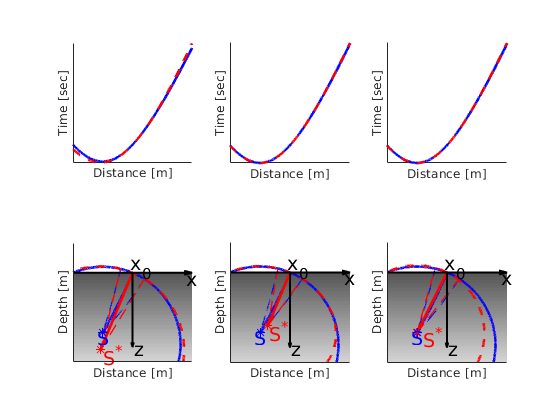

figure(1)
subplot(2,3,1)
plot(G.xx, tti(:,gx0z), 'b','LineWidth',2)
hold on
plot(G.xx, tti_o(:,gx0z)-(t0_o/2-t0/2), '--red','LineWidth',2)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Time [sec]')
axis('square')


subplot(2,3,2)
plot(G.xx, tti(:,gx0z), 'b','LineWidth',2)
hold on
plot(G.xx, tti_a(:,gx0z), '--red','LineWidth',2)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Time [sec]')
axis('square')


subplot(2,3,3)
plot(G.xx, tti(:,gx0z), 'b','LineWidth',2)
hold on
plot(G.xx, tti_e(:,gx0z), '--red','LineWidth',2)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Time [sec]')
axis('square')

subplot(2,3,4)
imagesc(G.xx, G.zz(501:2001), velmod_fig')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), tti',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), tti_o',[t0_o/2,t0_o/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(pray.xx, pray.zz, '--blue','LineWidth',1)
plot(mray.xx, mray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_o,x0(1),250), linspace(Sz_o,x0(2),250), '-red','LineWidth',2) 
plot(linspace(Sx_o,xm(1),250), linspace(Sz_o,xm(2),250), '--red','LineWidth',1) 
plot(linspace(Sx_o,xp(1),250), linspace(Sz_o,xp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_o, Sz_o, 'red*')
axis('equal')
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Depth [m]')
text(25,1275,'z','FontSize',14)
text(900,100,'x','FontSize',14)
text(-50,-100,'x_0','FontSize',14)
text(-600,1100,'S','FontSize',14,'Color','blue')
text(-500,1400,'S^*','FontSize',14,'Color','red')

subplot(2,3,5)
imagesc(G.xx, G.zz(501:2001), velmod_fig')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), tti',[t0/2,t0/2], 'Color', 'b','LineWidth',2)
contour(G.xx, G.zz(1:2001), tti_a',[t0_a/2,t0_a/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(pray.xx, pray.zz, '--blue','LineWidth',1)
plot(mray.xx, mray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_a,x0(1),250), linspace(Sz_a,x0(2),250), '-red','LineWidth',2) 
plot(linspace(Sx_a,xm(1),250), linspace(Sz_a,xm(2),250), '--red','LineWidth',1) 
plot(linspace(Sx_a,xp(1),250), linspace(Sz_a,xp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_a, Sz_a, 'red*')
axis('equal')
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Depth [m]')
text(25,1275,'z','FontSize',14)
text(900,100,'x','FontSize',14)
text(-50,-100,'x_0','FontSize',14)
text(-600,1100,'S','FontSize',14,'Color','blue')
text(-350,1000,'S^*','FontSize',14,'Color','red')


subplot(2,3,6)
imagesc(G.xx, G.zz(501:2001), velmod_fig')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), tti',[t0/2,t0/2], 'Color', 'b','LineWidth',2)
contour(G.xx, G.zz(1:2001), tti_e',[t0_e/2,t0_e/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(pray.xx, pray.zz, '--blue','LineWidth',1)
plot(mray.xx, mray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_e,x0(1),250), linspace(Sz_e,x0(2),250), '-red','LineWidth',2) 
plot(linspace(Sx_e,xm(1),250), linspace(Sz_e,xm(2),250), '--red','LineWidth',1) 
plot(linspace(Sx_e,xp(1),250), linspace(Sz_e,xp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_e, Sz_e, 'red*')
axis('equal')
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Depth [m]')

text(25,1275,'z','FontSize',14)
text(900,100,'x','FontSize',14)
text(-50,-100,'x_0','FontSize',14)
text(-600,1100,'S','FontSize',14,'Color','blue')
text(-400,1100,'S^*','FontSize',14,'Color','red')

## Figure normal experiment

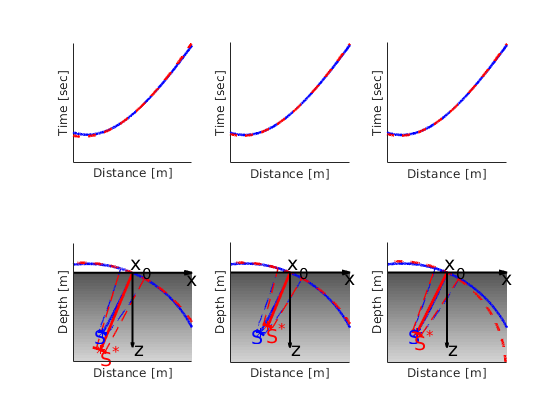

figure(2)
subplot(2,3,1)
plot(G.xx, ttiN(:,gx0z), 'b','LineWidth',2)
hold on
plot(G.xx, ttiN_o(:,gx0z)-(t0_o/2-t0/2), '--red','LineWidth',2)
set(gca,'xtick',[])
set(gca,'ytick',[])
axis([-1000 1000 0.4 1.0])
box off
xlabel('Distance [m]')
ylabel('Time [sec]')
axis('square')


subplot(2,3,2)
plot(G.xx, ttiN(:,gx0z), 'b','LineWidth',2)
hold on
plot(G.xx, ttiN_a(:,gx0z), '--red','LineWidth',2)
set(gca,'xtick',[])
set(gca,'ytick',[])
axis([-1000 1000 0.4 1.0])
box off
xlabel('Distance [m]')
ylabel('Time [sec]')
axis('square')


subplot(2,3,3)
plot(G.xx, ttiN(:,gx0z), 'b','LineWidth',2)
hold on
plot(G.xx, ttiN_e(:,gx0z), '--red','LineWidth',2)
set(gca,'xtick',[])
set(gca,'ytick',[])
axis([-1000 1000 0.4 1.0])
box off
xlabel('Distance [m]')
ylabel('Time [sec]')
axis('square')


subplot(2,3,4)
imagesc(G.xx, G.zz(501:2001), velmod_fig')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), ttiN',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), ttiN_o',[t0_o/2,t0_o/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(Npray.xx, Npray.zz, '--blue','LineWidth',1)
plot(Nmray.xx, Nmray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_o,x0(1),250), linspace(Sz_o,x0(2),250), '-red','LineWidth',2) 
Oxm = Ox_o + (Nxm(1) - Ox_o)*R_o/RN_o; 
Ozm = Oz_o + (Nxm(2) - Oz_o)*R_o/RN_o; 
Oxp = Ox_o + (Nxp(1) - Ox_o)*R_o/RN_o; 
Ozp = Oz_o + (Nxp(2) - Oz_o)*R_o/RN_o; 
plot(linspace(Oxm,Nxm(1),250), linspace(Ozm,Nxm(2),250), '--red','LineWidth',1) 
plot(linspace(Oxp,Nxp(1),250), linspace(Ozp,Nxp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(xr+R*cos(mtheta), zr+R*sin(mtheta), '-blue', 'LineWidth',2)
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_o, Sz_o, 'red*')
theta_o = -0.43*pi:pi/100:-0.33*pi;
plot(Ox_o+R_o*cos(theta_o), Oz_o+R_o*sin(theta_o), '-red', 'LineWidth',2)
axis('equal')
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Depth [m]')
text(25,1275,'z','FontSize',14)
text(900,100,'x','FontSize',14)
text(-50,-100,'x_0','FontSize',14)
text(-650,1075,'S','FontSize',14,'Color','blue')
text(-550,1425,'S^*','FontSize',14,'Color','red')


subplot(2,3,5)
imagesc(G.xx, G.zz(501:2001), velmod_fig')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), ttiN',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), ttiN_a',[t0_a/2,t0_a/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(Npray.xx, Npray.zz, '--blue','LineWidth',1)
plot(Nmray.xx, Nmray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_a,x0(1),250), linspace(Sz_a,x0(2),250), '-red','LineWidth',2) 
Oxm = Ox_a + (Nxm(1) - Ox_a)*R_a/RN_a; 
Ozm = Oz_a + (Nxm(2) - Oz_a)*R_a/RN_a; 
Oxp = Ox_a + (Nxp(1) - Ox_a)*R_a/RN_a; 
Ozp = Oz_a + (Nxp(2) - Oz_a)*R_a/RN_a; 
plot(linspace(Oxm,Nxm(1),250), linspace(Ozm,Nxm(2),250), '--red','LineWidth',1) 
plot(linspace(Oxp,Nxp(1),250), linspace(Ozp,Nxp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(xr+R*cos(mtheta), zr+R*sin(mtheta), '-blue', 'LineWidth',2)
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_a, Sz_a, 'red*')
theta_a = -0.43*pi:pi/100:-0.33*pi;
plot(Ox_a+R_a*cos(theta_a), Oz_a+R_a*sin(theta_a), '-red', 'LineWidth',2)
axis('equal')
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Depth [m]')
text(25,1275,'z','FontSize',14)
text(900,100,'x','FontSize',14)
text(-50,-100,'x_0','FontSize',14)
text(-650,1075,'S','FontSize',14,'Color','blue')
text(-400,1025,'S^*','FontSize',14,'Color','red')



subplot(2,3,6)
imagesc(G.xx, G.zz(501:2001), velmod_fig')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), ttiN',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), ttiN_e',[t0_e/2,t0_e/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(Npray.xx, Npray.zz, '--blue','LineWidth',1)
plot(Nmray.xx, Nmray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_e,x0(1),250), linspace(Sz_e,x0(2),250), '-red','LineWidth',2) 
Oxm = Ox_e + (Nxm(1) - Ox_e)*R_e/RN_e; 
Ozm = Oz_e + (Nxm(2) - Oz_e)*R_e/RN_e; 
Oxp = Ox_e + (Nxp(1) - Ox_e)*R_e/RN_e; 
Ozp = Oz_e + (Nxp(2) - Oz_e)*R_e/RN_e; 
plot(linspace(Oxm,Nxm(1),250), linspace(Ozm,Nxm(2),250), '--red','LineWidth',1) 
plot(linspace(Oxp,Nxp(1),250), linspace(Ozp,Nxp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(xr+R*cos(mtheta), zr+R*sin(mtheta), '-blue', 'LineWidth',2)
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_e, Sz_e, 'red*')
theta_e = -0.40*pi:pi/100:-0.30*pi;
plot(Ox_e+R_e*cos(theta_e), Oz_e+R_e*sin(theta_e), '-red', 'LineWidth',2)
axis('equal')
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
xlabel('Distance [m]')
ylabel('Depth [m]')
text(25,1275,'z','FontSize',14)
text(900,100,'x','FontSize',14)
text(-50,-100,'x_0','FontSize',14)
text(-650,1075,'S','FontSize',14,'Color','blue')
text(-550,1150,'S^*','FontSize',14,'Color','red')

## Figure 3 - NIP experiment (paper)

FigHandle = figure('Position', [100 100 1200 600])

FigHandle =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1200 600]
       Units: 'pixels'

  Show all properties


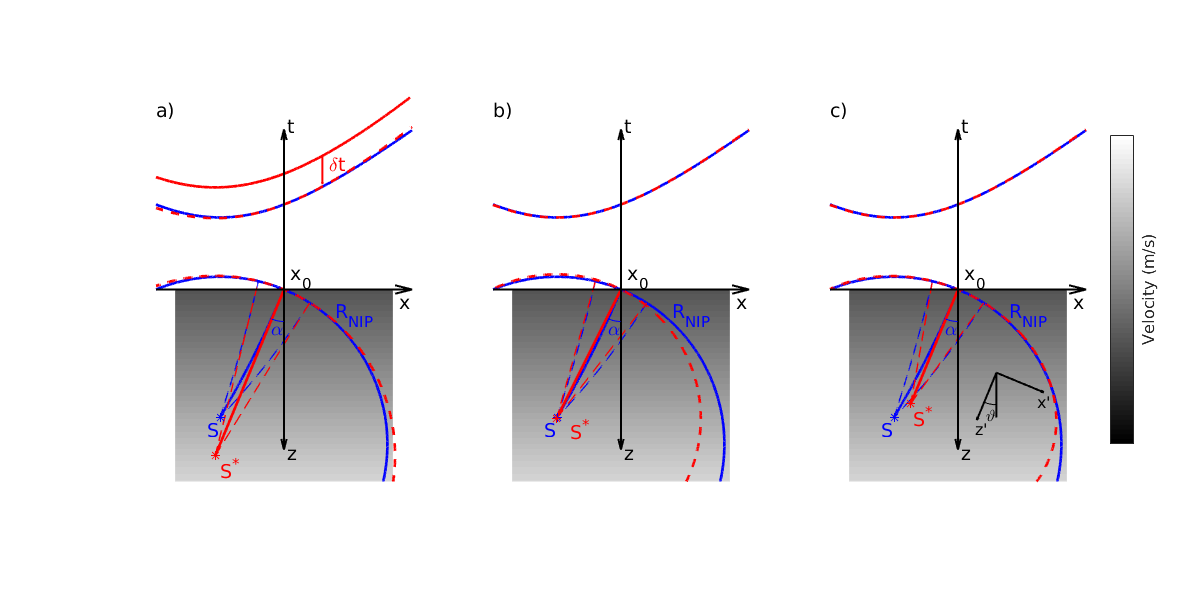

subplot(1,3,1)
plot(G.xx, -tti(:,gx0z)*1500+300, 'b','LineWidth',2)
hold on
plot(G.xx, -(tti_o(:,gx0z))*1500+500, 'red','LineWidth',2)
plot(G.xx, -(tti_o(:,gx0z)-(t0_o/2-t0/2))*1500+300, '--red','LineWidth',2)
imagesc(G.xx(151:1851), G.zz(501:2001), velmod_fig(151:1851,:)')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), tti',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), tti_o',[t0_o/2,t0_o/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(pray.xx, pray.zz, '--blue','LineWidth',1)
plot(mray.xx, mray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_o,x0(1),250), linspace(Sz_o,x0(2),250), '-red','LineWidth',2) 
plot(linspace(Sx_o,xm(1),250), linspace(Sz_o,xm(2),250), '--red','LineWidth',1) 
plot(linspace(Sx_o,xp(1),250), linspace(Sz_o,xp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_o, Sz_o, 'red*')
set(gca,'YDir','reverse');
axis('equal')
axis([-1000 1000 -1500 1500])
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,-1250,0,'Color', 'black','LineWidth',1.5)
quiver(300,-1046,0,221,0,'Color', 'red','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
text(25,1275,'z','FontSize',14)
text(25,-1275,'t','FontSize',14)
text(900,100,'x','FontSize',14)
text(50,-100,'x_0','FontSize',14)
text(-600,1100,'S','FontSize',14,'Color','blue')
text(-500,1400,'S^*','FontSize',14,'Color','red')
set(gca,'xcolor','w','ycolor','w','xtick',[],'ytick',[])
%title('Optical auxiliary medium')
text(-1000,-1400,'a)','FontSize',14,'Color','black')
text(-100,300,'\alpha','FontSize',14,'Color','blue')
text(400,200,'R_{NIP}','FontSize',14,'Color','blue')
text(350,-980,'{\delta}t','FontSize',14,'Color','red')
plot(250*sin(alpha:pi/100:0), 250*cos(alpha:pi/100:0), 'blue')

subplot(1,3,3)
plot(G.xx, -tti(:,gx0z)*1500+300, 'b','LineWidth',2)
hold on
plot(G.xx, -tti_a(:,gx0z)*1500+300, '--red','LineWidth',2)
imagesc(G.xx(151:1851), G.zz(501:2001), velmod_fig(151:1851,:)')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), tti',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), tti_a',[t0_a/2,t0_a/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(pray.xx, pray.zz, '--blue','LineWidth',1)
plot(mray.xx, mray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_a,x0(1),250), linspace(Sz_a,x0(2),250), '-red','LineWidth',2) 
plot(linspace(Sx_a,xm(1),250), linspace(Sz_a,xm(2),250), '--red','LineWidth',1) 
plot(linspace(Sx_a,xp(1),250), linspace(Sz_a,xp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_a, Sz_a, 'red*')
set(gca,'YDir','reverse');
axis('equal')
axis([-1000 1000 -1500 1500])
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,-1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
text(25,1275,'z','FontSize',14)
text(25,-1275,'t','FontSize',14)
text(900,100,'x','FontSize',14)
text(50,-100,'x_0','FontSize',14)
text(-600,1100,'S','FontSize',14,'Color','blue')
text(-350,1000,'S^*','FontSize',14,'Color','red')
set(gca,'xcolor','w','ycolor','w','xtick',[],'ytick',[])
%title('Anisotropic auxiliary medium')
text(-1000,-1400,'c)','FontSize',14,'Color','black')
text(-100,300,'\alpha','FontSize',14,'Color','blue')
text(400,200,'R_{NIP}','FontSize',14,'Color','blue')
plot(250*sin(alpha:pi/100:0), 250*cos(alpha:pi/100:0), 'blue')
quiver(300,650,-153,370,0,'Color', 'black','LineWidth',1.5)
quiver(300,650,370,153,0,'Color', 'black','LineWidth',1.5)
plot(linspace(300,300,250), linspace(650,1000,250), '-black','LineWidth',1.5)
plot(300+250*sin(alpha:pi/100:0), 650+250*cos(alpha:pi/100:0), 'black')
text(220,980,'\vartheta','FontSize',12,'Color','black')
text(620,880,'x''','FontSize',12)
text(130,1090,'z''','FontSize',12)

subplot(1,3,2)
plot(G.xx, -tti(:,gx0z)*1500+300, 'b','LineWidth',2)
hold on
plot(G.xx, -tti_e(:,gx0z)*1500+300, '--red','LineWidth',2)
imagesc(G.xx(151:1851), G.zz(501:2001), velmod_fig(151:1851,:)')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), tti',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), tti_e',[t0_e/2,t0_e/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(pray.xx, pray.zz, '--blue','LineWidth',1)
plot(mray.xx, mray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_e,x0(1),250), linspace(Sz_e,x0(2),250), '-red','LineWidth',2) 
plot(linspace(Sx_e,xm(1),250), linspace(Sz_e,xm(2),250), '--red','LineWidth',1) 
plot(linspace(Sx_e,xp(1),250), linspace(Sz_e,xp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_e, Sz_e, 'red*')
set(gca,'YDir','reverse');
axis('equal')
axis([-1000 1000 -1500 1500])
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,-1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
text(25,1275,'z','FontSize',14)
text(25,-1275,'t','FontSize',14)
text(900,100,'x','FontSize',14)
text(50,-100,'x_0','FontSize',14)
text(-600,1100,'S','FontSize',14,'Color','blue')
text(-400,1100,'S^*','FontSize',14,'Color','red')
set(gca,'xcolor','w','ycolor','w','xtick',[],'ytick',[])
%title('Effective auxiliary medium')
text(-1000,-1400,'b)','FontSize',14,'Color','black')
text(-100,300,'\alpha','FontSize',14,'Color','blue')
text(400,200,'R_{NIP}','FontSize',14,'Color','blue')
plot(250*sin(alpha:pi/100:0), 250*cos(alpha:pi/100:0), 'blue')

hp = get(subplot(1,3,3), 'Position');
c=colorbar('Ticks', [], 'Position', [hp(1)+hp(3)+0.02 hp(2)+0.15 0.02 hp(4)-0.3]);
c.Label.String = 'Velocity (m/s)';
c.Label.FontSize = 12;

## Figure 4 - Normal experiment (paper)

figure(4)
FigHandle = figure('Position', [100 100 1200 600])

FigHandle =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1200 600]
       Units: 'pixels'

  Show all properties


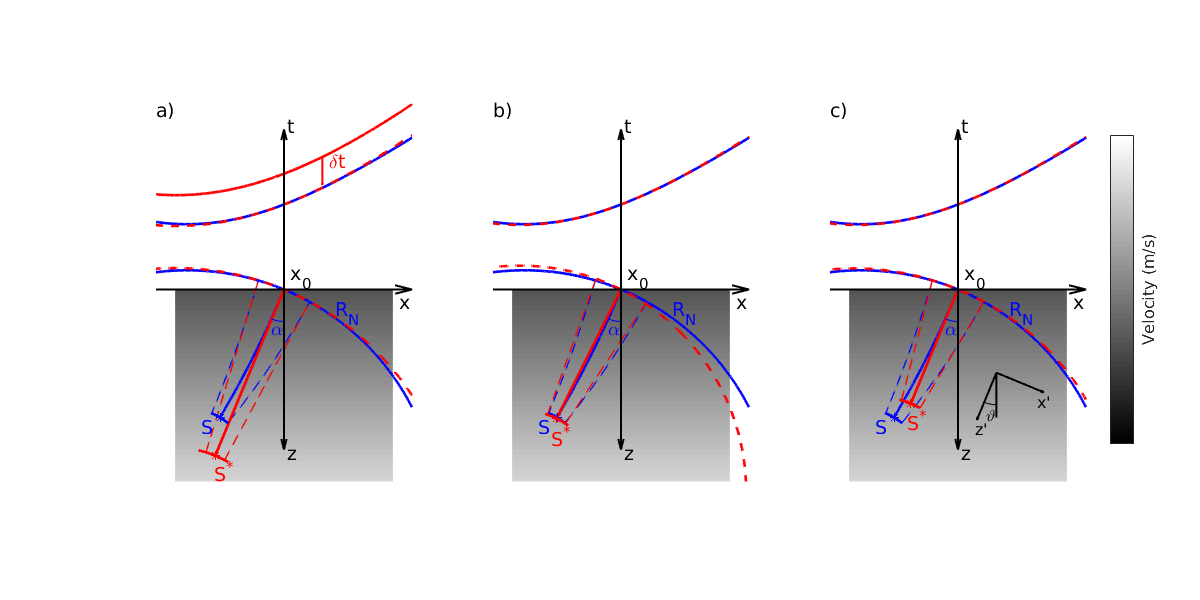

subplot(1,3,1)
plot(G.xx, -ttiN(:,gx0z)*1500+300, 'b','LineWidth',2)
hold on
plot(G.xx, -(ttiN_o(:,gx0z))*1500+500, 'red','LineWidth',2)
plot(G.xx, -(ttiN_o(:,gx0z)-(t0_o/2-t0/2))*1500+300, '--red','LineWidth',2)
imagesc(G.xx(151:1851), G.zz(501:2001), velmod_fig(151:1851,:)')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), ttiN',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), ttiN_o',[t0_o/2,t0_o/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(Npray.xx, Npray.zz, '--blue','LineWidth',1)
plot(Nmray.xx, Nmray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_o,x0(1),250), linspace(Sz_o,x0(2),250), '-red','LineWidth',2) 
Oxm = Ox_o + (Nxm(1) - Ox_o)*R_o/RN_o; 
Ozm = Oz_o + (Nxm(2) - Oz_o)*R_o/RN_o; 
Oxp = Ox_o + (Nxp(1) - Ox_o)*R_o/RN_o; 
Ozp = Oz_o + (Nxp(2) - Oz_o)*R_o/RN_o; 
plot(linspace(Oxm,Nxm(1),250), linspace(Ozm,Nxm(2),250), '--red','LineWidth',1) 
plot(linspace(Oxp,Nxp(1),250), linspace(Ozp,Nxp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(xr+R*cos(mtheta), zr+R*sin(mtheta), '-blue', 'LineWidth',2)
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_o, Sz_o, 'red*')
theta_o = -0.43*pi:pi/100:-0.33*pi;
plot(Ox_o+R_o*cos(theta_o), Oz_o+R_o*sin(theta_o), '-red', 'LineWidth',2)
set(gca,'YDir','reverse');
axis('equal')
axis([-1000 1000 -1500 1500])
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,-1250,0,'Color', 'black','LineWidth',1.5)
quiver(300,-1038,0,221,0,'Color', 'red','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
text(25,1275,'z','FontSize',14)
text(25,-1275,'t','FontSize',14)
text(900,100,'x','FontSize',14)
text(50,-100,'x_0','FontSize',14)
text(-650,1075,'S','FontSize',14,'Color','blue')
text(-550,1425,'S^*','FontSize',14,'Color','red')
text(350,-1000,'{\delta}t','FontSize',14,'Color','red')
set(gca,'xcolor','w','ycolor','w','xtick',[],'ytick',[])
%title('Optical auxiliary medium')
text(-1000,-1400,'a)','FontSize',14,'Color','black')
text(-100,300,'\alpha','FontSize',14,'Color','blue')
text(400,180,'R_{N}','FontSize',14,'Color','blue')
plot(250*sin(alpha:pi/100:0), 250*cos(alpha:pi/100:0), 'blue')

subplot(1,3,3)
plot(G.xx, -ttiN(:,gx0z)*1500+300, 'b','LineWidth',2)
hold on
plot(G.xx, -ttiN_e(:,gx0z)*1500+300, '--red','LineWidth',2)
imagesc(G.xx(151:1851), G.zz(501:2001), velmod_fig(151:1851,:)')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), ttiN',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), ttiN_a',[t0_a/2,t0_a/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(Npray.xx, Npray.zz, '--blue','LineWidth',1)
plot(Nmray.xx, Nmray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_a,x0(1),250), linspace(Sz_a,x0(2),250), '-red','LineWidth',2) 
Oxm = Ox_a + (Nxm(1) - Ox_a)*R_a/RN_a; 
Ozm = Oz_a + (Nxm(2) - Oz_a)*R_a/RN_a; 
Oxp = Ox_a + (Nxp(1) - Ox_a)*R_a/RN_a; 
Ozp = Oz_a + (Nxp(2) - Oz_a)*R_a/RN_a; 
plot(linspace(Oxm,Nxm(1),250), linspace(Ozm,Nxm(2),250), '--red','LineWidth',1) 
plot(linspace(Oxp,Nxp(1),250), linspace(Ozp,Nxp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(xr+R*cos(mtheta), zr+R*sin(mtheta), '-blue', 'LineWidth',2)
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_a, Sz_a, 'red*')
theta_a = -0.43*pi:pi/100:-0.33*pi;
plot(Ox_a+R_a*cos(theta_a), Oz_a+R_a*sin(theta_a), '-red', 'LineWidth',2)
set(gca,'YDir','reverse');
axis('equal')
axis([-1000 1000 -1500 1500])
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,-1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
text(25,1275,'z','FontSize',14)
text(25,-1275,'t','FontSize',14)
text(900,100,'x','FontSize',14)
text(50,-100,'x_0','FontSize',14)
text(-650,1075,'S','FontSize',14,'Color','blue')
text(-400,1025,'S^*','FontSize',14,'Color','red')
set(gca,'xcolor','w','ycolor','w','xtick',[],'ytick',[])
%title('Anisotropic auxiliary medium')
text(-1000,-1400,'c)','FontSize',14,'Color','black')
text(-100,300,'\alpha','FontSize',14,'Color','blue')
text(400,180,'R_{N}','FontSize',14,'Color','blue')
plot(250*sin(alpha:pi/100:0), 250*cos(alpha:pi/100:0), 'blue')
quiver(300,650,-153,370,0,'Color', 'black','LineWidth',1.5)
quiver(300,650,370,153,0,'Color', 'black','LineWidth',1.5)
plot(linspace(300,300,250), linspace(650,1000,250), '-black','LineWidth',1.5)
plot(300+250*sin(alpha:pi/100:0), 650+250*cos(alpha:pi/100:0), 'black')
text(220,980,'\vartheta','FontSize',12,'Color','black')
text(620,880,'x''','FontSize',12)
text(130,1090,'z''','FontSize',12)

subplot(1,3,2)
plot(G.xx, -ttiN(:,gx0z)*1500+300, 'b','LineWidth',2)
hold on
plot(G.xx, -ttiN_e(:,gx0z)*1500+300, '--red','LineWidth',2)
imagesc(G.xx(151:1851), G.zz(501:2001), velmod_fig(151:1851,:)')
colormap('gray')
hold on 
contour(G.xx, G.zz(1:2001), ttiN',[t0/2,t0/2], 'Color', 'b', 'LineWidth',2)
contour(G.xx, G.zz(1:2001), ttiN_e',[t0_e/2,t0_e/2], '--red','LineWidth',2)
plot(cray.xx, cray.zz, '-blue','LineWidth',2)
plot(Npray.xx, Npray.zz, '--blue','LineWidth',1)
plot(Nmray.xx, Nmray.zz, '--blue','LineWidth',1)
plot(linspace(Sx_e,x0(1),250), linspace(Sz_e,x0(2),250), '-red','LineWidth',2) 
Oxm = Ox_e + (Nxm(1) - Ox_e)*R_e/RN_e; 
Ozm = Oz_e + (Nxm(2) - Oz_e)*R_e/RN_e; 
Oxp = Ox_e + (Nxp(1) - Ox_e)*R_e/RN_e; 
Ozp = Oz_e + (Nxp(2) - Oz_e)*R_e/RN_e; 
plot(linspace(Oxm,Nxm(1),250), linspace(Ozm,Nxm(2),250), '--red','LineWidth',1) 
plot(linspace(Oxp,Nxp(1),250), linspace(Ozp,Nxp(2),250), '--red','LineWidth',1) 
plot(S(1), S(2), 'b*')
plot(xr+R*cos(mtheta), zr+R*sin(mtheta), '-blue', 'LineWidth',2)
plot(x0(1), x0(2), 'b.','LineWidth',2)
plot(Sx_e, Sz_e, 'red*')
theta_e = -0.40*pi:pi/100:-0.30*pi;
plot(Ox_e+R_e*cos(theta_e), Oz_e+R_e*sin(theta_e), '-red', 'LineWidth',2)
set(gca,'YDir','reverse');
axis('equal')
axis([-1000 1000 -1500 1500])
caxis([1000 2500])
quiver(-1000,0,2000,0,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,1250,0,'Color', 'black','LineWidth',1.5)
quiver(0,0,0,-1250,0,'Color', 'black','LineWidth',1.5)
set(gca,'xtick',[])
set(gca,'ytick',[])
box off
text(25,1275,'z','FontSize',14)
text(25,-1275,'t','FontSize',14)
text(900,100,'x','FontSize',14)
text(50,-100,'x_0','FontSize',14)
text(-650,1075,'S','FontSize',14,'Color','blue')
text(-550,1150,'S^*','FontSize',14,'Color','red')
set(gca,'xcolor','w','ycolor','w','xtick',[],'ytick',[])
%title('Effective auxiliary medium')
text(-1000,-1400,'b)','FontSize',14,'Color','black')
text(-100,300,'\alpha','FontSize',14,'Color','blue')
text(400,180,'R_{N}','FontSize',14,'Color','blue')
plot(250*sin(alpha:pi/100:0), 250*cos(alpha:pi/100:0), 'blue')

hp = get(subplot(1,3,3), 'Position');
c=colorbar('Ticks', [], 'Position', [hp(1)+hp(3)+0.02 hp(2)+0.15 0.02 hp(4)-0.3]);
c.Label.String = 'Velocity (m/s)';
c.Label.FontSize = 12;

## Figure 5

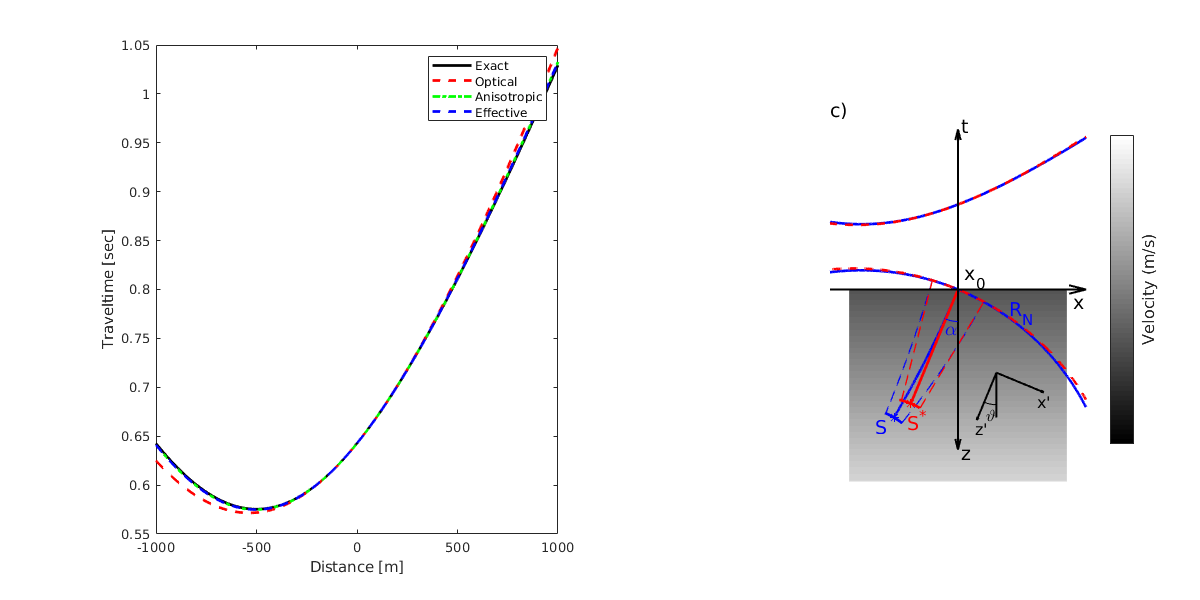

figure(5)
subplot(1,2,1)
plot(G.xx, tti(:,gx0z), '-black','LineWidth',2)
hold on 
plot(G.xx, tti_o(:,gx0z)-(t0_o/2-t0/2), '--red','LineWidth',2)
plot(G.xx, tti_a(:,gx0z), '-.green','LineWidth',2)
plot(G.xx, tti_e(:,gx0z), '--blue','LineWidth',2)
legend('Exact', 'Optical', 'Anisotropic', 'Effective'); 
xlabel('Distance [m]')
ylabel('Traveltime [sec]')

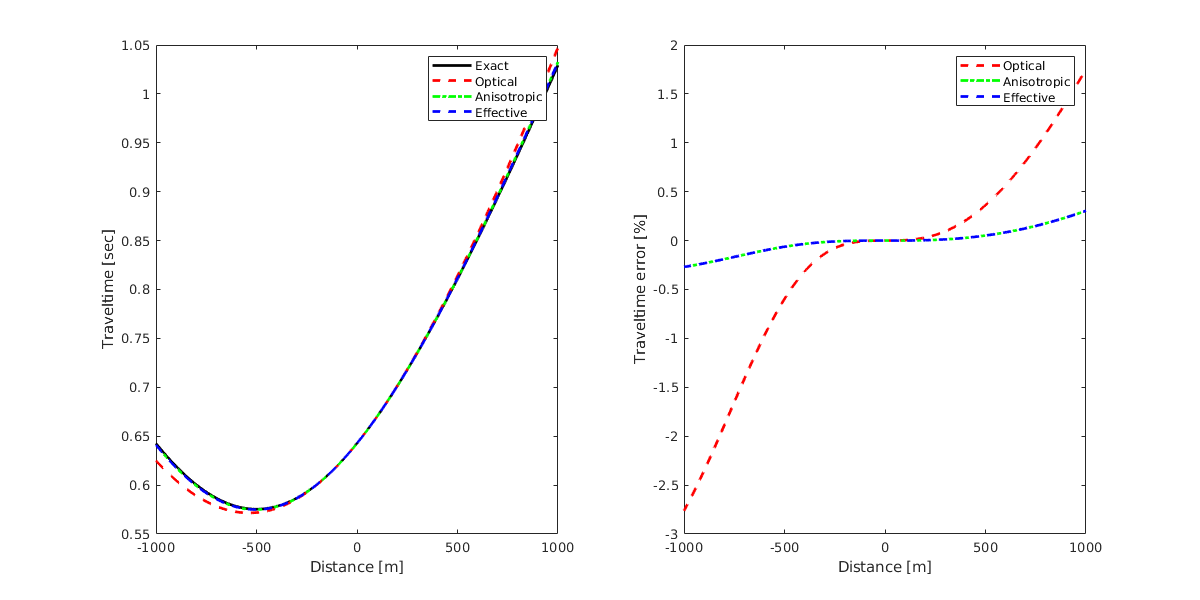


subplot(1,2,2)
plot(G.xx, (tti_o(:,gx0z)-(t0_o/2-t0/2)-tti(:,gx0z))./tti(:,gx0z)*100, '--red','LineWidth',2)
hold on
plot(G.xx, (tti_a(:,gx0z)-tti(:,gx0z))./tti(:,gx0z)*100, '-.green','LineWidth',2)
plot(G.xx, (tti_e(:,gx0z)-tti(:,gx0z))./tti(:,gx0z)*100, '--blue','LineWidth',2)
legend('Optical', 'Anisotropic', 'Effective'); 
xlabel('Distance [m]')
ylabel('Traveltime error [%]')

## Figure 6

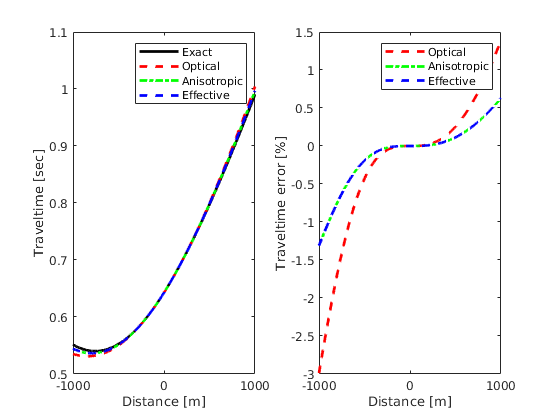

figure(6)
subplot(1,2,1)
plot(G.xx, ttiN(:,gx0z), '-black','LineWidth',2)
hold on 
plot(G.xx, ttiN_o(:,gx0z)-(t0_o/2-t0/2), '--red','LineWidth',2)
plot(G.xx, ttiN_a(:,gx0z), '-.green','LineWidth',2)
plot(G.xx, ttiN_e(:,gx0z), '--blue','LineWidth',2)
legend('Exact', 'Optical', 'Anisotropic', 'Effective'); 
xlabel('Distance [m]')
ylabel('Traveltime [sec]')

subplot(1,2,2)
plot(G.xx, (ttiN_o(:,gx0z)-(t0_o/2-t0/2)-ttiN(:,gx0z))./ttiN(:,gx0z)*100, '--red','LineWidth',2)
hold on
plot(G.xx, (ttiN_a(:,gx0z)-ttiN(:,gx0z))./ttiN(:,gx0z)*100, '-.green','LineWidth',2)
plot(G.xx, (ttiN_e(:,gx0z)-ttiN(:,gx0z))./ttiN(:,gx0z)*100, '--blue','LineWidth',2)
legend('Optical', 'Anisotropic', 'Effective'); 
xlabel('Distance [m]')
ylabel('Traveltime error [%]')

## Figure 7 (for paper)

figure(7)
FigHandle = figure('Position', [100 100 800 400])

FigHandle =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 800 400]
       Units: 'pixels'

  Show all properties


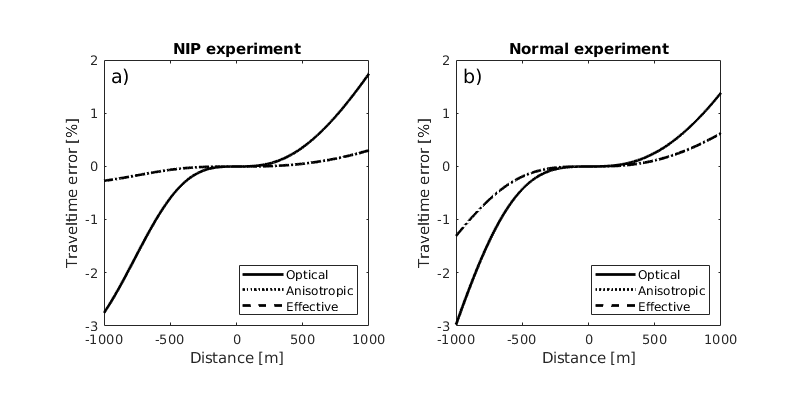


subplot(1,2,1)
plot(G.xx, (tti_o(:,gx0z)-(t0_o/2-t0/2)-tti(:,gx0z))./tti(:,gx0z)*100, '-k','LineWidth',2)
hold on
plot(G.xx, (tti_a(:,gx0z)-tti(:,gx0z))./tti(:,gx0z)*100, ':k','LineWidth',2)
plot(G.xx, (tti_e(:,gx0z)-tti(:,gx0z))./tti(:,gx0z)*100, '--k','LineWidth',2)
axis([-1000 1000 -3 2])
axis('square')
legend('Optical', 'Anisotropic', 'Effective', 'Location', 'southeast'); 
xlabel('Distance [m]')
ylabel('Traveltime error [%]')
title('NIP experiment')
text(-950,1.7,'a)','FontSize',14,'Color','black')

subplot(1,2,2)
plot(G.xx, (ttiN_o(:,gx0z)-(t0_o/2-t0/2)-ttiN(:,gx0z))./ttiN(:,gx0z)*100, '-k','LineWidth',2)
hold on
plot(G.xx, (ttiN_a(:,gx0z)-ttiN(:,gx0z))./ttiN(:,gx0z)*100, ':k','LineWidth',2)
plot(G.xx, (ttiN_e(:,gx0z)-ttiN(:,gx0z))./ttiN(:,gx0z)*100, '--k','LineWidth',2)
legend('Optical', 'Anisotropic', 'Effective', 'Location', 'southeast'); 
axis([-1000 1000 -3 2])
axis('square')
xlabel('Distance [m]')
ylabel('Traveltime error [%]')
title('Normal experiment')
text(-950,1.7,'b)','FontSize',14,'Color','black')

## Figure 8 (alternative, for paper)

figure(8)
FigHandle = figure('Position', [100 100 800 400])

FigHandle =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 800 400]
       Units: 'pixels'

  Show all properties


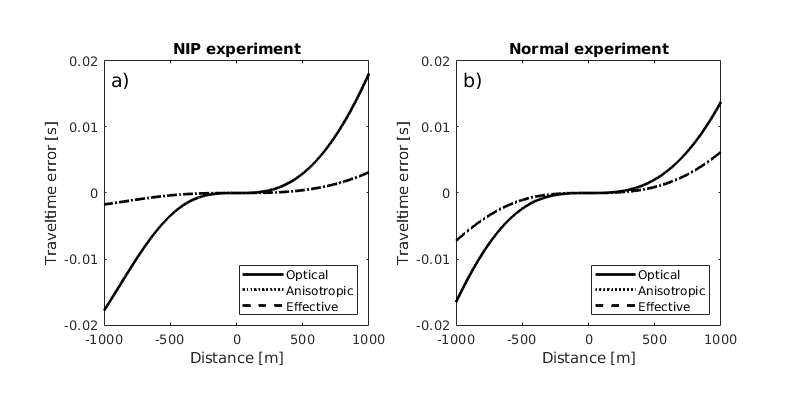


subplot(1,2,1)
plot(G.xx, (tti_o(:,gx0z)-(t0_o/2-t0/2)-tti(:,gx0z)), '-k','LineWidth',2)
hold on
plot(G.xx, (tti_a(:,gx0z)-tti(:,gx0z)), ':k','LineWidth',2)
plot(G.xx, (tti_e(:,gx0z)-tti(:,gx0z)), '--k','LineWidth',2)
axis([-1000 1000 -0.02 0.02])
axis('square')
legend('Optical', 'Anisotropic', 'Effective', 'Location', 'southeast'); 
xlabel('Distance [m]')
ylabel('Traveltime error [s]')
yticks([-0.02 -0.01 0 0.01 0.02])
title('NIP experiment')
text(-950,0.017,'a)','FontSize',14,'Color','black')

subplot(1,2,2)
plot(G.xx, (ttiN_o(:,gx0z)-(t0_o/2-t0/2)-ttiN(:,gx0z)), '-k','LineWidth',2)
hold on
plot(G.xx, (ttiN_a(:,gx0z)-ttiN(:,gx0z)), ':k','LineWidth',2)
plot(G.xx, (ttiN_e(:,gx0z)-ttiN(:,gx0z)), '--k','LineWidth',2)
legend('Optical', 'Anisotropic', 'Effective', 'Location', 'southeast'); 
axis([-1000 1000 -0.02 0.02])
axis('square')
xlabel('Distance [m]')
ylabel('Traveltime error [s]')
yticks([-0.02 -0.01 0 0.01 0.02])
title('Normal experiment')
text(-950,0.017,'b)','FontSize',14,'Color','black')